# Ingreso de datos por el usuario y visualización personalizada

## Función `input`

### Ejercicio

El volumen de un cono es


$$V=\frac{1}{3}A_b h$$


donde $A_h$ es el área de la base y $h$ es la altura del cono.

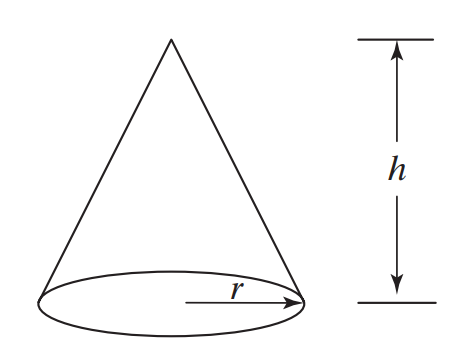

Conmine al usuario a ingresar el radio de la base circular y la altura del cono. Calcule el volumen del cono.

*Ejercicio modificado de Moore, 2007.*

### Solución

altura=input("Ingrese la altura del cono: ")

altura = 5

radio=input("Ingrese el radio del cono: ")

radio = 2

volumen=(1/3)*(pi*power(radio,2))*(altura) 

volumen = 20.9440

## Funciones de despliegue de información

### Ejercicio 1

Explique porqué estos dos códigos (el `disp` y los dos `fprintf`) generan la misma salida.

*Ejercicio tomado y modificado de Attaway, 2022.*

### Solución

Porque en la primera parte de fprintf no tiene el salto de linea "\n" por lo cual el siguiente fprintf lo hace seguido del primero

### Ejercicio 2

Conmine al usuario a ingresar un arreglo de números. Use la función `length` para determinar cuántos valores ingresó y use la función `disp` para reportar sus resultados a la ventana de comandos.

*Ejercicio tomado de Moore, 2007.*

### Solución

arreglo=input("Ingresa un vector de numeros: ");
num=length(arreglo);
disp(arreglo)

     1     2     3     4     5



fprintf("el numero de valores es: %d",num)

el numero de valores es: 5

### Ejercicio 3

Realizar las siguientes actividades:

- Solicitar al usuario su nombre, su edad y su estatura en metros.

- Suponiendo que se ha ingresado: Juan, 21 y 1.73, entonces desplegar por pantalla: "Hola. Mi nombre es Juan. Tengo 21 años y mido 1.73 m. ¡Es un placer conocerte!".

- Haciendo la suposición anterior, desplegar por pantalla lo indicado en el literal 2, pero cada espacio luego de un punto será ahora un salto de línea, a excepción del último punto donde en lugar de un salto de línea deberá haber dos saltos de línea.

### Solución

nombre=input("Ingresa tu primer nombre: ","s");
edad=input("Ingresa tu edad: ");
estutura=input("Ingresa tu estatura en metros: ");
%literal 1 
fprintf("Hola. mi nombre es %s. Tengo %u años y mido %.2f m. Es un placer!!", nombre,edad,estutura)

Hola. mi nombre es Alex. Tengo 19 años y mido 1.76 m. Es un placer!!

%literal 2 
fprintf("Hola\nMi nombre es %s\nTengo %u años y mido %.2f m\nEs un placer!!",nombre,edad,estutura)

Hola
Mi nombre es Alex
Tengo 19 años y mido 1.76 m
Es un placer!!

### Ejercicio 4

Use su buscador favorito de Internet y navegue la red para identificar conversiones monetarias recientes para libras esterlinas británicas, yen japonés y el euro europeo a dólares estadounidenses. Use las tablas de conversión para crear las siguientes tablas (use los comandos `disp` y `fprintf` en su solución, que debe incluir un título, etiquetas de columna y salida formateada):

- Genere una tabla de conversiones de yen a dólar. Comience la columna yen en 5 e incremente por 5 yen. Imprima 25 líneas en la tabla.

- Genere una tabla de conversiones de euros a dólares. Comience la columna euro en 1 euro e incremente por 2 euros. Imprima 30 líneas en al tabla.

- Genere una tabla con cuatro columnas. La primera debe contener dólares, la segunda debe contener el número equivalente de euros, la tercera el número equivalente de libras y la cuarta el número equivalente de yen. Haga que la columna dólar varíe de 1 a 10.

*Ejercicio tomado de Moore, 2007.*

### Solución

EJERCICIO 1 

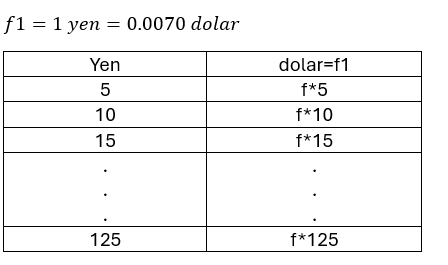

%ejer 1 
f1=0.0070;
yen=5:5:125;
dolar=f1*yen;
M=[yen ; dolar];
disp("...Conversion de yen a dolar...");fprintf("\t|\tyen\t|\tdolar\t|\n");fprintf("\t|\t%.3f\t|\t%.3f\t|\n",M)

...Conversion de yen a dolar...
	|	yen	|	dolar	|
	|	5.000	|	0.035	|
	|	10.000	|	0.070	|
	|	15.000	|	0.105	|
	|	20.000	|	0.140	|
	|	25.000	|	0.175	|
	|	30.000	|	0.210	|
	|	35.000	|	0.245	|
	|	40.000	|	0.280	|
	|	45.000	|	0.315	|
	|	50.000	|	0.350	|
	|	55.000	|	0.385	|
	|	60.000	|	0.420	|
	|	65.000	|	0.455	|
	|	70.000	|	0.490	|
	|	75.000	|	0.525	|
	|	80.000	|	0.560	|
	|	85.000	|	0.595	|
	|	90.000	|	0.630	|
	|	95.000	|	0.665	|
	|	100.000	|	0.700	|
	|	105.000	|	0.735	|
	|	110.000	|	0.770	|
	|	115.000	|	0.805	|
	|	120.000	|	0.840	|
	|	125.000	|	0.875	|


EJERCICIO 2 

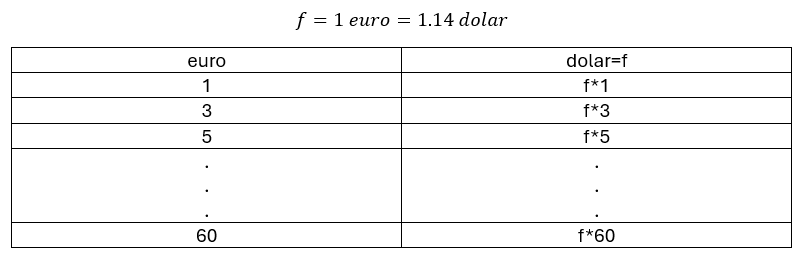

%ejer 2 
f2=1.14;
euro=1:2:60;
dolar=f2*euro;
M=[euro ; dolar];
disp("...Conversion de euro a dolar...");fprintf("\t|\teuro\t|\tdolar\t|\n");fprintf("\t|\t%.3f\t|\t%.3f\t|\n",M)

...Conversion de euro a dolar...
	|	euro	|	dolar	|
	|	1.000	|	1.140	|
	|	3.000	|	3.420	|
	|	5.000	|	5.700	|
	|	7.000	|	7.980	|
	|	9.000	|	10.260	|
	|	11.000	|	12.540	|
	|	13.000	|	14.820	|
	|	15.000	|	17.100	|
	|	17.000	|	19.380	|
	|	19.000	|	21.660	|
	|	21.000	|	23.940	|
	|	23.000	|	26.220	|
	|	25.000	|	28.500	|
	|	27.000	|	30.780	|
	|	29.000	|	33.060	|
	|	31.000	|	35.340	|
	|	33.000	|	37.620	|
	|	35.000	|	39.900	|
	|	37.000	|	42.180	|
	|	39.000	|	44.460	|
	|	41.000	|	46.740	|
	|	43.000	|	49.020	|
	|	45.000	|	51.300	|
	|	47.000	|	53.580	|
	|	49.000	|	55.860	|
	|	51.000	|	58.140	|
	|	53.000	|	60.420	|
	|	55.000	|	62.700	|
	|	57.000	|	64.980	|
	|	59.000	|	67.260	|


EJERCICIO 3

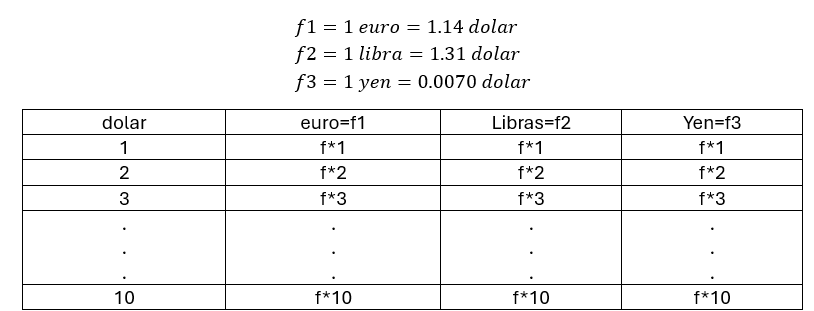

%ejer 3 
f3=1.31;
dolar=1:10;
yen=f1*dolar;
euro=f2*dolar;
libras=f3*dolar;
M=[dolar ; euro ; libras ; yen];
disp("...Conversion de euro a dolar...");fprintf("\t|\tdolar\t|\teuro\t|\tlibras\t|\tyen\t|\n");fprintf("\t|\t%.3f\t|\t%.3f\t|\t%.3f\t|\t%.3f\t|\n",M)

...Conversion de euro a dolar...
	|	dolar	|	euro	|	libras	|	yen	|
	|	1.000	|	1.140	|	1.310	|	0.007	|
	|	2.000	|	2.280	|	2.620	|	0.014	|
	|	3.000	|	3.420	|	3.930	|	0.021	|
	|	4.000	|	4.560	|	5.240	|	0.028	|
	|	5.000	|	5.700	|	6.550	|	0.035	|
	|	6.000	|	6.840	|	7.860	|	0.042	|
	|	7.000	|	7.980	|	9.170	|	0.049	|
	|	8.000	|	9.120	|	10.480	|	0.056	|
	|	9.000	|	10.260	|	11.790	|	0.063	|
	|	10.000	|	11.400	|	13.100	|	0.070	|
